clear 

% W203
W203_4Dir = './W203_4';
W203_5Dir = './W203_5';
% C12_1 10 序列
C12_1_4Dir = './C12_1_4';
C12_1_5Dir = './C12_1_5';
% C12_2 10 序列
C12_2_4Dir = './C12_2_4';
C12_2_5Dir = './C12_2_5';

DirName = C12_1_5Dir;
FileTable = GetMATFile(DirName,1);
Nfile = size(FileTable,1); 


Distance.org = nan;
Distance.h = nan;
Hdop.org = nan;
Hdop.h = nan;
 
for iFile = 1:Nfile
    FileName = FileTable(iFile,:);
    [distanceFilter,hdopFiltered] = AnalysisCdf(DirName,FileName);
    
    Distance.org = [Distance.org;distanceFilter.org];
    Distance.h = [Distance.h;distanceFilter.h];
    
    Hdop.org = [Hdop.org;hdopFiltered.org];
    Hdop.h = [Hdop.h;hdopFiltered.h];
end

ans = 47

ans = 60

ans = 298

ans = 145

ans = 62

ans = 75

ans = 197

ans = 240

ans = 80

ans = 65

ans = 248

ans = 259

ans = 111

ans = 87

ans = 357

ans = 213

ans = 33

ans = 67

ans = 119

ans = 194

ans = 0

ans = 48

ans = 20

ans = 269

ans = 50

ans = 81

ans = 167

ans = 272

ans = 0

ans = 10

ans = 20

ans = 204

ans = 232

ans = 141

ans = 564

ans = 300

ans = 102

ans = 124

ans = 564

ans = 300

ans = 221

ans = 132

ans = 560

ans = 269

ans = 190

ans = 133

ans = 593

ans = 276

ans = 221

ans = 117

ans = 572

ans = 257

ans = 210

ans = 99

ans = 553

ans = 222


% 一个补丁
Distance.org = Distance.org(2:end);
Distance.h = Distance.h(2:end);

Hdop.org = Hdop.org(2:end);
Hdop.h = Hdop.h(2:end);



ts = 'sat=5,50%';

length(Distance.org)

ans = 1559

length(Distance.h)

ans = 1239

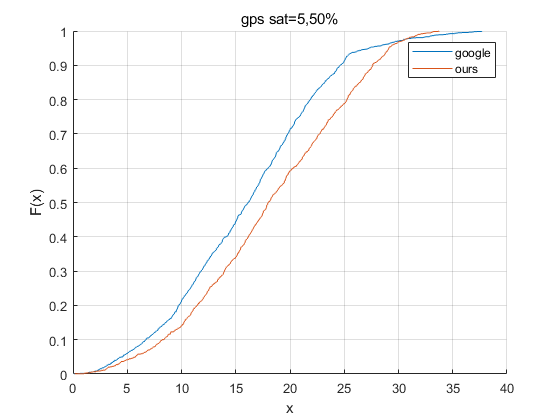

figure
hold on
cdfplot(Distance.org)
cdfplot(Distance.h)
legend('google','ours')
title(['gps ' ts])
hold off


length(Hdop.org)

ans = 4832

length(Hdop.h)

ans = 3420

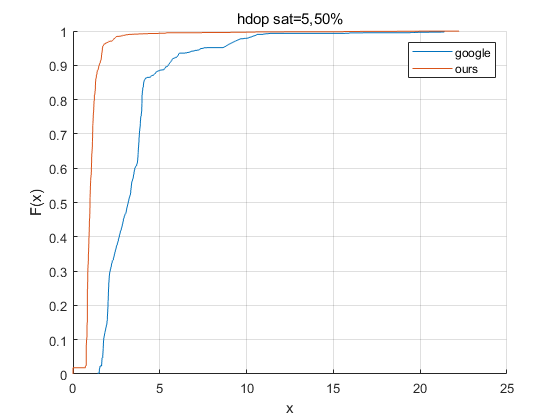

figure
hold on
cdfplot(Hdop.org)
cdfplot(Hdop.h)
legend('google','ours')
title(['hdop ' ts])
hold off